# Pellet Smoker: Model B

## Set Particulars

p.C_f = 500;
p.k_f = 150;
p.k_ca = 25;
p.C_c = 2500;
p.k_fa = 20;
p.gamma = 1000;
p.T_amb = 25;
p.u_p_max = 10;
p.u_p_min = 0;
p.u_f_max = 1;
p.u_f_min = 0;
if true % uncertainty in model
    sigma = 0.80;
    p.C_f = 500*(1 + sigma * randn);
    p.k_f = 150*(1 + sigma * randn);
    p.k_ca = 25*(1 + sigma * randn);
    p.C_c = 2500*(1 + sigma * randn);
    p.k_fa = 20*(1 + sigma * randn);
    p.gamma = 1000*(1 + sigma * randn);
    p.T_amb = 25*(1 + sigma * randn);
end

Unrecognized function or variable 't_lookup'.

## Integral Action

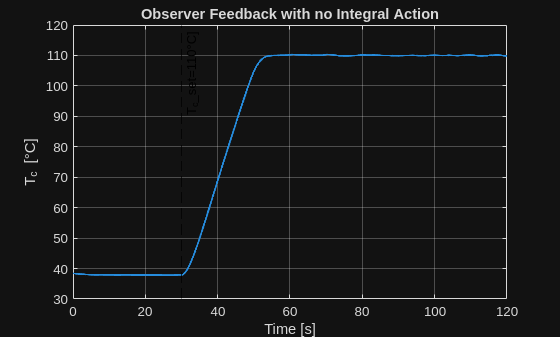

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 120;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=30)*p.T_amb+(t>30&&t<=600)*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) (t>=50)&&(t<20);

% Comparative simulations on integral action
[basic.t, basic.x_aug, basic.u] = run_simulation(p, sim_params, @basic_observer, @basic_feedback);
[int.t, int.x_aug, int.u] = run_simulation(p, sim_params, @integral_observer, @integral_feedback);
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);

figure;
plot(basic.t, basic.x_aug(2,:), 'LineWidth', 1.5); hold on;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C]']);
title('Observer Feedback with no Integral Action');
grid on;
xline(30,  '--k', ['T_c\_set=110' char(176) 'C]'],  'LabelHorizontalAlignment','right');

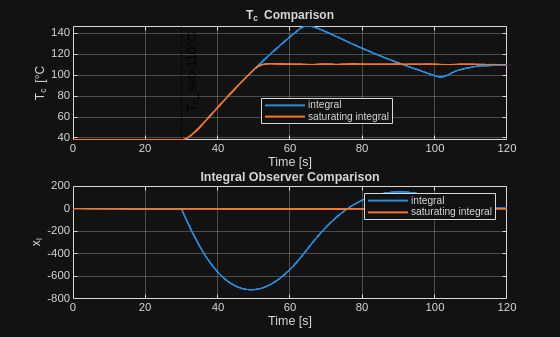


% plot
figure;
title("Anti-Windup Integral Action vs Saturating Integral Action")
subplot(2,1,1);
plot(int.t,   int.x_aug(2,:),   'LineWidth', 1.5); hold on;
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5);
xline(30,  '--k', ['T_c\_set=110' char(176) 'C'],  'LabelHorizontalAlignment','right');
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c Comparison');
legend('integral', 'saturating integral');
grid on;
subplot(2,1,2);
plot(int.t, int.x_aug(7,:), 'LineWidth', 1.5); hold on;
plot(sat.t, sat.x_aug(7,:), 'LineWidth', 1.5);
hold off;
xlabel('Time [s]');
ylabel('x_I');
title('Integral Observer Comparison');
legend('integral', 'saturating integral');
grid on;

## Disturbance Rejection

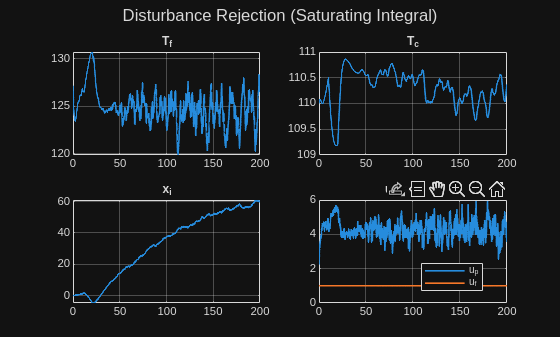

% initialization points
sim_params.T_c_start = 110;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 200;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz (noise sampling rate)
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) 110;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) (t>=10)&&(t<20);

% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);

% plot
figure;
sgtitle("Disturbance Rejection (Saturating Integral)")
subplot(2,2,1);
plot(sat.t, sat.x_aug(1,:), 'LineWidth', 1.2);
title('T_f');
grid on;
subplot(2,2,2);
plot(sat.t, sat.x_aug(2,:), 'LineWidth', 1.2);
title('T_c');
grid on;
subplot(2,2,3);
plot(sat.t, sat.x_aug(7,:), 'LineWidth', 1.2);
title('x_i');
grid on;
subplot(2,2,4);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
grid on;

## Profile Tracking

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0 % never

sim_params = struct with fields:
          T_c_start: 1.5081
          m_p_start: 10000
              t_min: 0
              t_max: 1800
                lin: [1×1 struct]
    noise_bandwidth: 100
    noise_amplitude: 0.0100
           setpoint: @(t)[Tce2Tfe(p,T_c_set_series(t));T_c_set_series(t);0]
        door_status: @(t)0


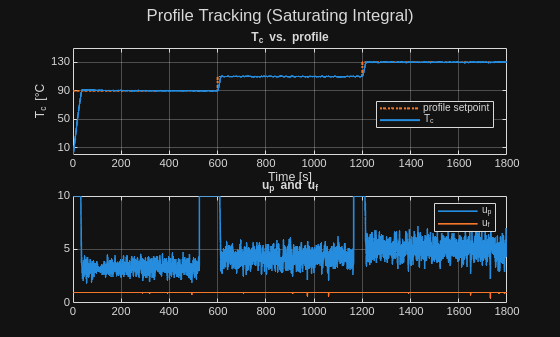


% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @saturating_integral_observer, @integral_feedback);

% plot
figure;
sgtitle("Profile Tracking (Saturating Integral)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## Comparitive Profile Tracking (Open Loop)

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0; % never

% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @open_loop);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## Profile Tracking (PI Controller)

% initialization points
sim_params.T_c_start = p.T_amb;
sim_params.m_p_start = 10000;
% linearization and timeseries
sim_params.t_min = 0;
sim_params.t_max = 1800;
sim_params.lin = linearize(p, [0.4; 0.6]);
% noise parameters
sim_params.noise_bandwidth = 100; % Hz
sim_params.noise_amplitude = 0.01; % normal to y
T_c_set_series = @(t) (t<=600)*90+((t>600).*(t<=1200))*110+(t>1200)*130;
sim_params.setpoint = @(t) [Tce2Tfe(p,T_c_set_series(t)); T_c_set_series(t); 0];
sim_params.door_status = @(t) 0; % never

% Simulation for Profile Tracking
[sat.t, sat.x_aug, sat.u] = run_simulation(p, sim_params, @integral_only, @open_loop);

% plot
figure;
sgtitle("Profile Tracking (Open Loop)")
subplot(2,1,1);
plot(sat.t,   sat.x_aug(2,:),   'LineWidth', 1.5); hold on;
set = T_c_set_series(sat.t);
h2 = plot(sat.t,set,   'LineWidth', 1.5, 'LineStyle', ':');
uistack(h2, 'bottom');
legend('profile setpoint', 'T_c')
hold off;
xlabel('Time [s]');
ylabel(['T_c [' char(176) 'C']);
title('T_c vs. profile');
yticks([10 50 90 130]);
xlim([0 1800])
grid on;
subplot(2,1,2);
plot(sat.t, sat.u(1,:), 'LineWidth', 1.2); hold on;
plot(sat.t, sat.u(2,:), 'LineWidth', 1.2);
title('u_p and u_f');
legend('u_p','u_f');
xlim([0 1800])
grid on;

## checking out noise

noise_bandwidth = 10; % Hz
noise_amplitude = 0.1; % normalized to y
t_min = sim_params.t_min;
t_max = sim_params.t_max;
noise_times = linspace(t_min, t_max, (t_max-t_min)*noise_bandwidth);
noise_values = noise_amplitude*randn(size(noise_times));
noise = @(t) interp1(noise_times, noise_values, t); % 1000 Hz sampling rate of the measuring device, let's say

## Test

size(sim_params.setpoint(1))
feed_struct.x_hat = x_hat;
feed_struct.x_I = 3;
feed_struct.lin = lin;
feed_struct.setpoint = setpoint;
feed_struct.y = 3;
saturate(feedback_wrapper(@integral_feedback, feed_struct)+op_point2u(p,setpoint(1)), [p.u_p_max; p.u_f_max], [p.u_p_min; p.u_f_min])